## Load Video

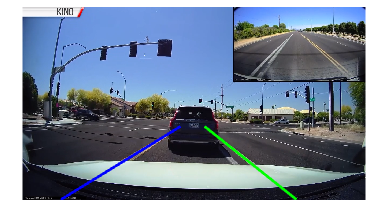

clear; close all; clc;

%% --- Cấu hình ---
VIDEO_PATH = 'car.mp4';
OUT_DIR = 'output';
if ~exist(OUT_DIR, 'dir')
    mkdir(OUT_DIR);
end

%% --- Đọc video ---
vidObj = VideoReader(VIDEO_PATH);
vidOut = VideoWriter(fullfile(OUT_DIR, 'lane_vehicle_output.mp4'), 'MPEG-4');
vidOut.FrameRate = vidObj.FrameRate;
open(vidOut);

frame_idx = 0;
total_time = 0;
correct_frames = 0;     % Frame có đủ lane trái + lane phải
total_frames = 0;       

while hasFrame(vidObj)
    frame = readFrame(vidObj);
    frame_idx = frame_idx + 1;
    total_frames = total_frames + 1;
    [h, w, ~] = size(frame);
    % --- Chuyển sang grayscale ---
    gray = rgb2gray(frame);

    % --- Lane detection với Canny ---
    edge_lane = canny_edges(gray, 30, 90);
    roi_pts = build_trapezoid_roi(size(gray), 0.6, 0.95, 0.6);
    [edges_roi, mask_roi] = apply_roi_mask(edge_lane, roi_pts);
    [left_line, right_line] = hough_lane_lines(edges_roi, size(gray));
    
    %[left_line, right_line] = get_lane(edges_roi, size(gray));

    % --- Vehicle edges ---
    veh_edges = sobel_morph_edges(gray);
   

    % --- Vẽ lane và edges ---
    frame_with_lanes = overlay_lane_lines(frame, left_line, right_line, veh_edges, 0.5);
    % Vẽ bounding boxes    
    % ================= HIỂN THỊ TRUNG GIAN =================
    
     %% ======= Tính Accuracy =======
    lane_ok = ~isempty(left_line) && ~isempty(right_line);
    if lane_ok
        correct_frames = correct_frames + 1;
    end
    
    %img_resized = imresize(frame_with_lanes, [722 1280]);  % [height width]

    % --- Ghi ra video ---
    writeVideo(vidOut, frame_with_lanes);

    % --- Lưu frame ra video ---
    %frame_out = getframe(gca);
    %writeVideo(vidOut, frame_out.cdata);
end

    

    % --- Tính thời gian cho frame ---
    elapsed = toc;
    total_time = total_time + elapsed;
    fprintf('Frame %d xử lý trong %.4f giây\n', frame_idx, elapsed);

Frame 383 xử lý trong 280.0033 giây




    % ========================================================
    
    % --- Tính toán chỉ số tốc độ ---
    avg_time = total_time / frame_idx;
    FPS = 1 / avg_time;
    accuracy_ratio = correct_frames / total_frames;
    fprintf('\n=== KẾT QUẢ ===\n');


=== KẾT QUẢ ===


    fprintf('Số frame: %d\n', frame_idx);

Số frame: 383


    fprintf('Thời gian trung bình mỗi frame: %.4f giây\n', avg_time);

Thời gian trung bình mỗi frame: 0.7311 giây


    fprintf('FPS trung bình: %.2f\n', FPS);

FPS trung bình: 1.37


    fprintf('Accuracy Ratio: %.2f%%\n', accuracy_ratio * 100);

Accuracy Ratio: 73.63%




close(vidOut);
disp('Hoàn tất lane + vehicle edge detection và lưu video.');

Hoàn tất lane + vehicle edge detection và lưu video.


## Image graying processing

function imshow_rgb(img_bgr, title_str, fig_size)
    if nargin < 2
        title_str = '';
    end
    if nargin < 3
        fig_size = 12;
    end

    % Nếu ảnh là nhị phân (logical), chuyển sang RGB
    if islogical(img_bgr)
        img_bgr = uint8(img_bgr) * 255;
        img_bgr = cat(3, img_bgr, img_bgr, img_bgr);
    end

    % Nếu ảnh chỉ có 1 kênh (grayscale), chuyển sang RGB
    if size(img_bgr, 3) == 1
        img_bgr = cat(3, img_bgr, img_bgr, img_bgr);
    end

    % Chuyển BGR -> RGB nếu có 3 kênh
    img_rgb = img_bgr(:, :, [3 2 1]);

    figure('Units', 'inches', 'Position', [1 1 fig_size fig_size*9/16]);
    imshow(img_rgb);
    if ~isempty(title_str)
        title(title_str);
    end
end

%% Hàm tạo ROI hình thang
function pts = build_trapezoid_roi(img_size, top_width_ratio, bottom_width_ratio, height_ratio)
    if nargin < 2, top_width_ratio = 0.15; end
    if nargin < 3, bottom_width_ratio = 0.9; end
    if nargin < 4, height_ratio = 0.55; end

    h = img_size(1);
    w = img_size(2);

    top_y = round(h * height_ratio);
    bottom_y = h; % MATLAB index từ 1
    half_top = round(w * top_width_ratio * 0.5);
    half_bot = round(w * bottom_width_ratio * 0.5);
    cx = round(w / 2);

    pts = [cx - half_top, top_y;
           cx + half_top, top_y;
           cx + half_bot, bottom_y;
           cx - half_bot, bottom_y];
end

%% Hàm áp dụng ROI mask
function [masked, mask] = apply_roi_mask(img, roi_pts)
    mask = poly2mask(roi_pts(:,1), roi_pts(:,2), size(img,1), size(img,2));

    if ndims(img) == 3
        masked = bsxfun(@times, img, cast(mask, class(img)));
    else
        masked = img .* cast(mask, class(img));
    end
end



## Canny edge extraction

function edges = canny_edges(gray, low_thresh, high_thresh)
    
    if nargin < 2
        low_thresh = 30;
    end
    if nargin < 3
        high_thresh = 90;
    end

    % Làm mượt ảnh (Gaussian blur)
    blur = imgaussfilt(gray, 1.0);  % sigma = 1.0, kernel 5x5 tự động
    
    % Áp dụng Canny
    edges = edge(blur, 'Canny', [low_thresh high_thresh]/255); 
    % MATLAB edge nhận ngưỡng 0-1, nên chia 255
end

## Hough translation extraction lane line

%% Hàm tính trung bình slope và intercept cho lane
function [left_line, right_line] = average_slope_intercept(lines, img_size)
    % lines: cấu trúc từ houghlines
    % img_size: [height, width]

    h = img_size(1);
    left_pts = [];
    right_pts = [];

    if isempty(lines)
        left_line = [];
        right_line = [];
        return;
    end

    % Xét từng line
    for k = 1:length(lines)
        xy = [lines(k).point1; lines(k).point2]; % [x1 y1; x2 y2]
        x1 = xy(1,1); y1 = xy(1,2);
        x2 = xy(2,1); y2 = xy(2,2);

        if x2 == x1
            continue;
        end
        slope = (y2 - y1) / (x2 - x1 + 1e-6);
        if abs(slope) < 0.5
            continue;
        end
        intercept = y1 - slope * x1;

        
        cx = img_size(2)/2;
        if slope < 0 
            left_pts = [left_pts; slope, intercept]; 
        else 
            right_pts = [right_pts; slope, intercept]; 
        end
     end

    % Hàm tạo line từ slope/intercept
    function line = make_line(avg, y1, y2)
        m = avg(1); b = avg(2);
        x1 = round((y1 - b) / (m + 1e-6));
        x2 = round((y2 - b) / (m + 1e-6));
        line = [x1, y1, x2, y2];
    end

    left_line = []; right_line = [];
    y1 = h - 1;
    y2 = round(h * 0.62);

    if ~isempty(left_pts)
        left_avg = mean(left_pts, 1);
        left_line = make_line(left_avg, y1, y2);
    end

    if ~isempty(right_pts)
        right_avg = mean(right_pts, 1);
        right_line = make_line(right_avg, y1, y2);
    end
end

%% Hàm phát hiện lane bằng Hough Transform
function [left_line, right_line] = hough_lane_lines(edge_img, img_size)

    % Thực hiện Hough Transform
    [H,theta,rho] = hough(edge_img);
    P = houghpeaks(H, 20, 'threshold', ceil(0.2*max(H(:))));
    lines_struct = houghlines(edge_img, theta, rho, P, ...
                              'FillGap', 200, 'MinLength', 20);

    % Lấy lane trái/phải trung bình
    [left_line, right_line] = average_slope_intercept(lines_struct, img_size);
end

## Sobel edge extraction

function opened = sobel_morph_edges(gray)
    % Làm mượt ảnh
    gray_blur = imgaussfilt(gray, 1.0);

    % Sobel theo x và y
    sobelx = imfilter(double(gray_blur), fspecial('sobel')', 'replicate'); % kênh x
    sobely = imfilter(double(gray_blur), fspecial('sobel'), 'replicate');  % kênh y

    % Kết hợp gradient (tương tự cv2.addWeighted(abs(sobelx),1,abs(sobely),1))
    sobel = abs(sobelx) + abs(sobely);
    sobel = uint8(255 * mat2gray(sobel));  % scale về 0-255

    % Nhị phân với Otsu
    level = graythresh(sobel);  % trả về 0-1
    th = imbinarize(sobel, level);

    % Morphological opening
    se = strel('rectangle', [5 5]);
    opened = imopen(th, se);
end

## draw lane line

function frame_out = overlay_lane_lines(frame, left_line, right_line, veh_edges, alpha)
frame_overlay = frame;
imshow(frame_overlay); hold on;
if ~isempty(left_line)
    plot([left_line(1) left_line(3)], [left_line(2) left_line(4)], 'LineWidth', 2, 'Color', 'blue');
end
if ~isempty(right_line)
    plot([right_line(1) right_line(3)], [right_line(2) right_line(4)], 'LineWidth', 2, 'Color', 'green');
end
hold off;
drawnow;

% --- Chuyển figure thành ảnh để lưu ---
frame_out = getframe(gca);
frame_out = frame_out.cdata;
end